clc;
clearvars;
close all;
format long g


carpetaActual = pwd;
versionMATLAB = version;
variablesIniciales = whos;

% Punto 1
% Código estudiante: 202411276

d=[2 0 2 4 1 1 2 7 6]

d =      2     0     2     4     1     1     2     7     6


p=d(7) + 2;       
q=d(8) + 3;     
r=d(9) + 4; 
theta=10*d(4) + d(5);

%1.1 y 1.2
E1_deg=(sind(theta) + cosd(p+q)^2 + r^-1)/(log10(p^2+q^2+10) + (log(r+20)/sqrt(p^2+q^2+r^2)));
E1_rad = (sin(theta) + cos(p+q)^2 + r^-1)/(log10(p^2+q^2+10) + log(r+20)/sqrt(p^2+q^2+r^2));

E2=((p+q)^2/tand(theta+5))*log(r+1) + nthroot(((p+r)*exp(-q/10))/log2(p*q+r+2), 3);

fprintf('E1 (theta en grados)   = %.10f\n', E1_deg);

E1 (theta en grados)   = 0.7279947376


fprintf('E1 (theta en radianes) = %.10f\n', E1_rad);

E1 (theta en radianes) = -0.0171222775



fprintf('E2 = %.10f\n', E2);

E2 = 454.8283645578



%1.3

variables = {'p';'q';'r';'theta';'E1';'E2'};
datos = [p; q; r; theta; E1_deg; E2];
clases  = {class(p); class(q); class(r); class(theta); class(E1_deg); class(E2)};

Tabla = table(variables, datos, clases, 'VariableNames', {'Variable','Dato','Clase'})

Tabla = 6×3 table
    Variable           Dato             Clase   
    _________    _________________    __________

    {'p'    }                    4    {'double'}
    {'q'    }                   10    {'double'}
    {'r'    }                   10    {'double'}
    {'theta'}                   41    {'double'}
    {'E1'   }    0.727994737623012    {'double'}
    {'E2'   }     454.828364557774    {'double'}



format short
disp(Tabla)

    Variable      Dato        Clase   
    _________    _______    __________

    {'p'    }          4    {'double'}
    {'q'    }         10    {'double'}
    {'r'    }         10    {'double'}
    {'theta'}         41    {'double'}
    {'E1'   }    0.72799    {'double'}
    {'E2'   }     454.83    {'double'}




format long
disp(Tabla)

    Variable           Dato             Clase   
    _________    _________________    __________

    {'p'    }                    4    {'double'}
    {'q'    }                   10    {'double'}
    {'r'    }                   10    {'double'}
    {'theta'}                   41    {'double'}
    {'E1'   }    0.727994737623012    {'double'}
    {'E2'   }     454.828364557774    {'double'}




%fprintf('--- Tabla con fprintf ---\n');
%fprintf('p     = %.10f (clase: %s)\n', p, class(p));
%fprintf('q     = %.10f (clase: %s)\n', q, class(q));
%fprintf('r     = %.10f (clase: %s)\n', r, class(r));
%fprintf('theta = %.10f (clase: %s)\n', theta, class(theta));
%fprintf('E1    = %.10f (clase: %s)\n', E1_deg, class(E1_deg));
%fprintf('E2    = %.10f (clase: %s)\n', E2, class(E2));

%2,1

%Matrices
A = [p q r; q+r p+1 q-1; r-p q+2 p+r]

A =      4    10    10
    20     5     9
     6    12    14


B = [r+1 p-1 q; p+q r 1; q-r p+2 r+2]

B =     11     3    10
    14    10     1
     0     6    12



vector_fila = [p q r p+r];              
vector_columna = [p; q; r; p+r];           
matriz_diagonal = diag([p q r]);            
matriz_toep = toeplitz([p q r]);

function info_arreglo(nombre_arreglo, arreglo)

    tamano = size(arreglo);
    num_filas = tamano(1);
    num_columnas = tamano(2);
    cantidad_elementos = numel(arreglo); 
    tipo_dato = class(arreglo); 
    valor_min = min(arreglo(:));  
    valor_max = max(arreglo(:)); 
    memoria = whos('arreglo');
    memoria_ocupada = memoria.bytes;

    fprintf('%s\n', nombre_arreglo);
    fprintf('Tamaño: %d filas x %d columnas\n', num_filas, num_columnas);
    fprintf('# de elementos: %d\n', cantidad_elementos);
    fprintf('Clase: %s\n', tipo_dato);
    fprintf('Mínimo: %g | Máximo: %g\n', valor_min, valor_max);
    fprintf('Memoria ocupada: %d bytes\n\n', memoria_ocupada);
end

info_arreglo('Vector fila', vector_fila);

Vector fila
Tamaño: 1 filas x 4 columnas
# de elementos: 4
Clase: double
Mínimo: 4 | Máximo: 14
Memoria ocupada: 32 bytes



info_arreglo('Vector columna', vector_columna);

Vector columna
Tamaño: 4 filas x 1 columnas
# de elementos: 4
Clase: double
Mínimo: 4 | Máximo: 14
Memoria ocupada: 32 bytes



info_arreglo('Matriz diagonal', matriz_diagonal);

Matriz diagonal
Tamaño: 3 filas x 3 columnas
# de elementos: 9
Clase: double
Mínimo: 0 | Máximo: 10
Memoria ocupada: 72 bytes



info_arreglo('Matriz de Toeplitz', matriz_toep);

Matriz de Toeplitz
Tamaño: 3 filas x 3 columnas
# de elementos: 9
Clase: double
Mínimo: 4 | Máximo: 10
Memoria ocupada: 72 bytes




%2.2
suma = A + B;
producto_AB = A * B;   
producto_BA = B * A;
prod_Elemento = A .* B;
div_Elemento = A ./ B;

disp('A + B ='); disp(suma)

A + B =
    15    13    20
    34    15    10
     6    18    26



disp('A*B ='); disp(producto_AB)

A*B =
   184   172   170
   290   164   313
   234   222   240



disp('B*A ='); disp(producto_BA)

B*A =
   164   245   277
   262   202   244
   192   174   222



disp('A.*B ='); disp(prod_Elemento)

A.*B =
    44    30   100
   280    50     9
     0    72   168



disp('A./B ='); disp(div_Elemento)

A./B =
   0.363636363636364   3.333333333333333   1.000000000000000
   1.428571428571429   0.500000000000000   9.000000000000000
                 Inf   2.000000000000000   1.166666666666667




verificacion_AB_21= A(2,1)*B(1,1) + A(2,2)*B(2,1) + A(2,3)*B(3,1);
fprintf('Verificación manual AB(2,1) = %g | MATLAB AB(2,1) = %g\n', verificacion_AB_21, producto_AB(2,1));

Verificación manual AB(2,1) = 290 | MATLAB AB(2,1) = 290



%2.3
C = [4 2 7; 3 5 9];
try
    incompatible = A*C;
catch Mensaje_error
    fprintf('Mensaje de MATLAB:\n%s\n\n', Mensaje_error.message);
    fprintf('Dimensiones A: %dx%d | Dimensiones C: %dx%d\n', size(A,1), size(A,2), size(C,1), size(C,2));
end

Mensaje de MATLAB:
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To operate on each element of the matrix individually, use TIMES (.*) for elementwise multiplication.



Dimensiones A: 3x3 | Dimensiones C: 2x3



correccion_1 = C*A

correccion_1 =     98   134   156
   166   163   201


disp('C*A ='); disp(correccion_1)

C*A =
    98   134   156
   166   163   201



fprintf('Corrección 1 C*A:| Dimensiones = %dx%d\n',size(correccion_1,1), size(correccion_1,2));

Corrección 1 C*A:| Dimensiones = 2x3


C_tranpuesta = C'; 
correccion_2 = A*C_tranpuesta;
disp('A*C'' ='); disp(correccion_2)

A*C' =
   106   152
   153   166
   146   204



fprintf('Corrección 2 A*C''| Dimensiones = %dx%d\n',size(correccion_2,1), size(correccion_2,2));

Corrección 2 A*C'| Dimensiones = 3x2


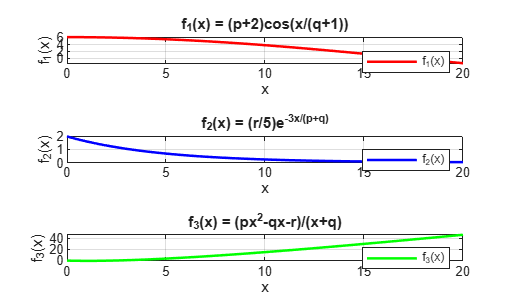


%3.1
x = 0:0.1:20; 
f1 = (p+2)*cos(x/(q+1));
f2 = (r/5)*exp(-3*x/(p+q));
f3 = (p*x.^2 - q*x - r)./(x+q);

figure
tiledlayout(3,1)

nexttile
plot(x, f1, 'r-', 'LineWidth', 1.5)
title('f_1(x) = (p+2)cos(x/(q+1))')
xlabel('x')
ylabel('f_1(x)')
grid on
legend('f_1(x)')

nexttile
plot(x, f2, 'b-', 'LineWidth', 1.5)
title('f_2(x) = (r/5)e^{-3x/(p+q)}')
xlabel('x')
ylabel('f_2(x)')
grid on
legend('f_2(x)')

nexttile
plot(x, f3, 'g-', 'LineWidth', 1.5)
title('f_3(x) = (px^2-qx-r)/(x+q)')
xlabel('x')
ylabel('f_3(x)')
grid on
legend('f_3(x)')


%3.2

f0 = d(9)

f0 =      6


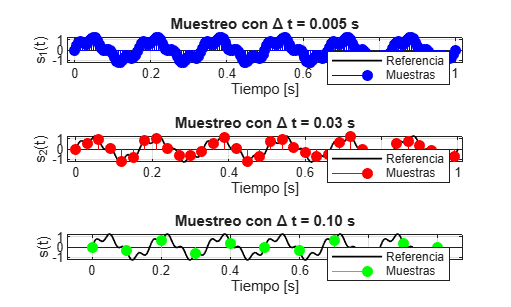


t1 = 0:0.005:1;  
s1 = sin(2*pi*f0*t1) + 0.35*sin(8*pi*f0*t1);
t2 = 0:0.03:1;  
s2 = sin(2*pi*f0*t2) + 0.35*sin(8*pi*f0*t2);
t3 = 0:0.10:1;  
s3 = sin(2*pi*f0*t3) + 0.35*sin(8*pi*f0*t3);

referencia_t = 0:0.001:1;
referencia_s = sin(2*pi*f0*referencia_t) + 0.35*sin(8*pi*f0*referencia_t);

figure
tiledlayout(3,1)
nexttile
plot(referencia_t, referencia_s, 'k-', 'LineWidth', 1)
hold on
stem(t1,s1,'b','filled')
hold off
title('Muestreo con \Delta t = 0.005 s')
xlabel('Tiempo [s]')
ylabel('s_1(t)')
grid on
legend('Referencia', 'Muestras')

nexttile
plot(referencia_t, referencia_s, 'k-', 'LineWidth', 1)
hold on
stem(t2,s2,'r','filled')
hold off
title('Muestreo con \Delta t = 0.03 s')
xlabel('Tiempo [s]')
ylabel('s_2(t)')
grid on
legend('Referencia', 'Muestras')

nexttile
plot(referencia_t, referencia_s, 'k-', 'LineWidth', 1)
hold on
stem(t3, s3,'g', 'filled')
hold off
title('Muestreo con \Delta t = 0.10 s')
xlabel('Tiempo [s]')
ylabel('s(t)')
grid on
legend('Referencia', 'Muestras')


%4.1

M = [-7  9 35 -3 16  12;
     15  5 15 98 54  -6;
     18 -1 13 57 -2  55;
     22  0 41 33 87  81;
     36  7 -4 15 69 -34;
     -9 65 70 -8  5  25];

%Punto a 

B = M(3,6);     
C = M(:,5); %toda la columna 5
D = M(2:5,3:6); %submatriz

fprintf('B = M(3,6) = %d\n', B);

B = M(3,6) = 55


disp('C = M(:,5) ='); disp(C)

C = M(:,5) =
    16
    54
    -2
    87
    69
     5



disp('D = M(2:5,3:6) ='); disp(D)

D = M(2:5,3:6) =
    15    98    54    -6
    13    57    -2    55
    41    33    87    81
    -4    15    69   -34




%Punto b

E = diag(M);
F = [];
for i = 1:6
    for j = 1:6
        if j > i
            F = [F M(i,j)];
        end
    end
end

disp('E =')

E =


disp(E')

    -7     5    13    33    69    25



disp('F =')

F =


disp(F)

     9
    35
    -3
    16
    12
    15
    98
    54
    -6
    57
    -2
    55
    87
    81
   -34




%Punto c

negativos = M(M<0);
[fila_neg, columna_neg] = find(M < 0);
disp('Valores negativos de M'); disp(negativos')

Valores negativos de M
    -7    -9    -1    -4    -3    -8    -2    -6   -34



disp('Posiciones de negativos:'); disp([fila_neg columna_neg])

Posiciones de negativos:
     1     1
     6     1
     3     2
     5     3
     1     4
     6     4
     3     5
     2     6
     5     6




media = mean(M(:));
fprintf('Media de M: %.4f\n', media);

Media de M: 24.5556


mayores_media = M(M > media);
[fila_mayor_media, columna_mayor_media] = find(M > media); 
disp('Valores mayores que la media:'); disp(mayores_media')

Valores mayores que la media:
    36    65    35    41    70    98    57    33    54    87    69    55    81    25



disp('Posiciones de mayores que la media:'); disp([fila_mayor_media columna_mayor_media])

Posiciones de mayores que la media:
     5     1
     6     2
     1     3
     4     3
     6     3
     2     4
     3     4
     4     4
     2     5
     4     5
     5     5
     3     6
     4     6
     6     6




[valores,indices] = sort(abs(M(:)),'descend');
top3_valores = M(indices(1:3));
top3_posiciones = indices(1:3); 
[top3_fila, top3_columna] = ind2sub(size(M), top3_posiciones);
disp('Top 3 valores de mayor magnitud absoluta:'); disp(top3_valores')

Top 3 valores de mayor magnitud absoluta:
    98    87    81



disp('En posiciones:'); disp([top3_fila top3_columna]);

En posiciones:
     2     4
     4     5
     4     6




%Punto d 
mu = mean(M,1);
sigma = std(M,0,1);
Z = (M - mu)./sigma;
media_Z = mean(Z,1);
sigma_Z = std(Z,0,1);
disp('Z (matriz normalizada) ='); disp(Z)
disp('Media de cada columna de Z:'); disp(media_Z)
disp('Desv. estándar de cada columna de Z:'); disp(sigma_Z)

%Punto e

sub1 = [M(3,1) M(4,3); M(1,4) M(5,1)];
sub2 = [M(2,3) M(2,5); M(6,3) M(1,5)];
sub3 = [M(1,1) M(6,6); M(2,2) M(3,3)];

disp('sub1 ='); disp(sub1)
disp('sub2 ='); disp(sub2)
disp('sub3 ='); disp(sub3)
disp('sub3''(transpuesta) ='); disp(sub3')
fprintf('Dimensiones: sub1=%dx%d, sub2=%dx%d, sub3''=%dx%d\n',size(sub1,1), size(sub1,2), size(sub2,1), size(sub2,2), ...
    size(sub3',1), size(sub3',2));
G = sub1 * sub2 + sub3';
disp('G ='); disp(G)
verificacion_G11 = sub1(1,1)*sub2(1,1) + sub1(1,2)*sub2(2,1) + sub3(1,1);
fprintf('Verificación manual G(1,1) = %d | MATLAB: G(1,1) = %d\n', verificacion_G11, G(1,1));